clear

# **SPRO3 - WS Interface**

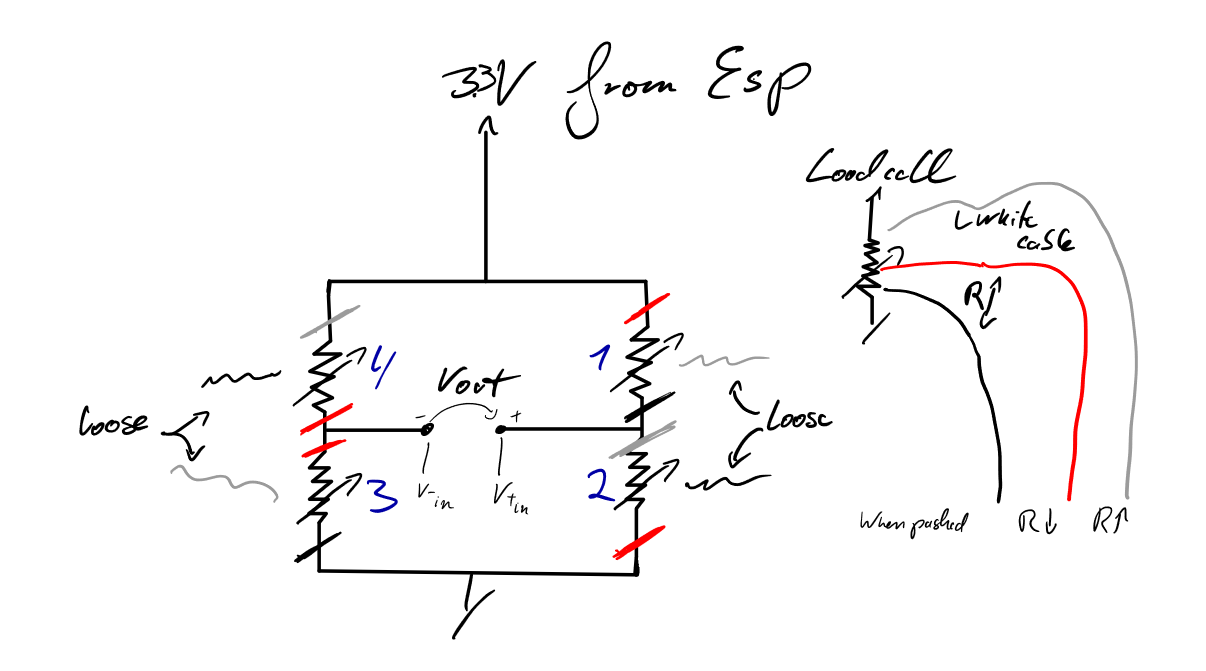

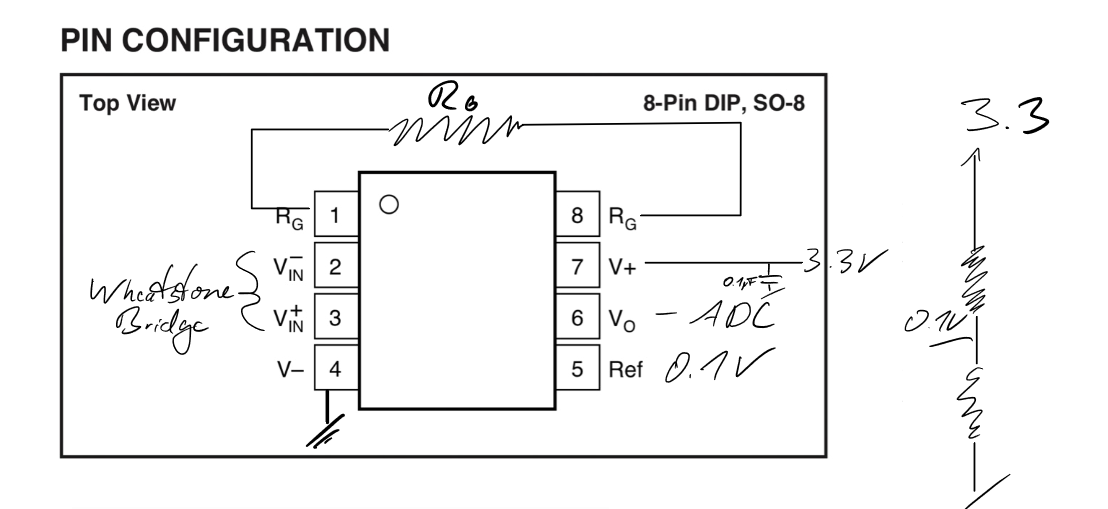

# Desired Range for the ADC

Vin_ADC_min = 0.2

Vin_ADC_min = 0.2000

Vin_ADC_max = 2.25

Vin_ADC_max = 2.2500


O_span = Vin_ADC_max - Vin_ADC_min

O_span = 2.0500

# Data Input from measurements

V_out_ESP = 3.3; % V
V_supply_wheatstone = V_out_ESP; % V

% Numbering of the loadcells is clockwise starting in the upper right
% corner - up is where the power supply goes in

% np: not pressed
% pd: pressed down
% Rwr: Resistance between white and red cable
% Rrb: Resistance between red and black cable

loadcell1 = struct('npRwr',1000,'npRrb',1000,'pdRwr',1001,'pdRrb',997);
loadcell2 = struct('npRwr',1000,'npRrb',1000,'pdRwr',1001,'pdRrb',997);
loadcell3 = struct('npRwr',1000,'npRrb',1000,'pdRwr',1001,'pdRrb',997);
loadcell4 = struct('npRwr',1000,'npRrb',1000,'pdRwr',1001,'pdRrb',997);


# Construction of Wheatstone Bridge

#### Scenario - No load

R1 = loadcell1.npRrb

R1 = 1000

R2 = loadcell2.npRwr

R2 = 1000

R3 = loadcell3.npRrb

R3 = 1000

R4 = loadcell4.npRwr

R4 = 1000


V_out_wheatstone_np = V_supply_wheatstone * (R2/(R1+R2)) - V_supply_wheatstone * (R3/(R3+R4))

V_out_wheatstone_np = 0

I_l12_np = V_supply_wheatstone / (R1 + R2)

I_l12_np = 0.0016

I_l34_np = V_supply_wheatstone / (R3 + R4)

I_l34_np = 0.0016

#### Scenario - Full load

R1 = loadcell1.pdRrb

R1 = 997

R2 = loadcell2.pdRwr

R2 = 1001

R3 = loadcell3.pdRrb

R3 = 997

R4 = loadcell4.pdRwr

R4 = 1001


V_out_wheatstone_pd = V_supply_wheatstone * (R2/(R1+R2)) - V_supply_wheatstone * (R3/(R3+R4))

V_out_wheatstone_pd = 0.0066

I_l12_pd = V_supply_wheatstone / (R1 + R2)

I_l12_pd = 0.0017

I_l34_pd = V_supply_wheatstone / (R3 + R4)

I_l34_pd = 0.0017


I_span = V_out_wheatstone_pd - V_out_wheatstone_np;

# Gain resistor and offset

desired_Gain = O_span / I_span

desired_Gain = 310.2955


syms R_G
required_R_G = vpasolve(desired_Gain == 5 + 200*10^3/R_G, R_G) 

$$required\_R\_G = 655.10310429537032243421388199204$$



% Voltage divider at Vref
